syms s
a=450/(s^4+3*s^3+10*s^2+30*s+150)

$$a = \frac{450}{s^{4}+3\,s^{3}+10\,s^{2}+30\,s+150}$$

b=(s^5+3*s^4+10*s^3+30*s^2+150*s+450)/(s^5+3*s^4+10*s^3+30*s^2+150*s)

$$b = \frac{s^{5}+3\,s^{4}+10\,s^{3}+30\,s^{2}+150\,s+450}{s^{5}+3\,s^{4}+10\,s^{3}+30\,s^{2}+150\,s}$$

c=a/b

$$c = \frac{450\,\left(s^{5}+3\,s^{4}+10\,s^{3}+30\,s^{2}+150\,s\right)}{\left(s^{4}+3\,s^{3}+10\,s^{2}+30\,s+150\right)\,\left(s^{5}+3\,s^{4}+10\,s^{3}+30\,s^{2}+150\,s+450\right)}$$

d=a/(1+a/s)

$$d = \frac{450}{\left(\frac{450}{s\,\left(s^{4}+3\,s^{3}+10\,s^{2}+30\,s+150\right)}+1\right)\,\left(s^{4}+3\,s^{3}+10\,s^{2}+30\,s+150\right)}$$


%1
A=[1 10 150 0]

A =      1    10   150     0


B=[3 30 450 0]

B =      3    30   450     0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1)...
-det([A(1) A(4) ;B(1) B(4)])/B(1) 0];
C=[12 60 0 0]

C =     12    60     0     0


D=[-det([B(1) B(2) ;C(1) C(2)])/C(1) -det([B(1) B(3) ;C(1) C(3)])/C(1)...
-det([B(1) B(4) ;C(1) C(4)])/C(1) 0]

D =     15   450     0     0


E=[-det([C(1) C(2) ;D(1) D(2)])/D(1) -det([C(1) C(3) ;D(1) D(3)])/D(1)...
-det([C(1) C(4) ;D(1) D(4)])/D(1) 0]

E =   -300     0     0     0


F=[-det([D(1) D(2) ;E(1) E(2)])/E(1) -det([D(1) D(3) ;E(1) E(3)])/E(1)...
-det([D(1) D(4) ;E(1) E(4)])/E(1) 0]

F =    450     0     0     0


g=tf([450 0],[1 3 10 30 150 450])

g =
 
                     450 s
  -------------------------------------------
  s^5 + 3 s^4 + 10 s^3 + 30 s^2 + 150 s + 450
 
Continuous-time transfer function.
Model Properties


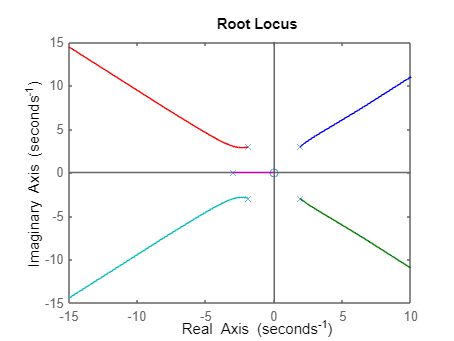

rlocus(g)

roots([1 3 10 30 150 450])

ans =    1.9036 + 2.9366i
   1.9036 - 2.9366i
  -1.9036 + 2.9366i
  -1.9036 - 2.9366i
  -3.0000 + 0.0000i




%2
k=2.15

k = 2.1500

A=[k+1 7*k-15 0]

A =     3.1500    0.0500         0


B=[8*k-2 0 0]

B =    15.2000         0         0


C=[-det([A(1) A(2) ;B(1) B(2)])/B(1) -det([A(1) A(3) ;B(1) B(3)])/B(1) 0]

C =     0.0500         0         0




%3
kp = limit(1020*(s+13)*(s+26)*(s+33)/((s+65)*(s+75)*(s+91)), s, 0)

$$kp = \frac{4488}{175}$$

kv = limit((s)*1020*(s+13)*(s+26)*(s+33)/((s+65)*(s+75)*(s+91)), s, 0)

$$kv = 0$$

ka = limit((s^2)*1020*(s+13)*(s+26)*(s+33)/((s+65)*(s+75)*(s+91)), s, 0)

$$ka = 0$$


estep = 15 / (1 + kp)

$$estep = \frac{2625}{4663}$$

eramp = 15 / kv

$$eramp = \infty$$

eparabol = 30 / ka

$$eparabol = \infty$$